# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

clearvars -except commonPath
plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Input Signals1

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
clear inputPath latestSlow latestFast
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Globals

delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
KpStatic = 50;
KiStatic = 1000;
tdStatic=0.04;

# Figure Path

figurePath = strcat(commonPath,'\Golden Figures');

# Model

%Model Setup
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'FastRestart','off')
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize) %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

% rat_I = 4.971;

# Setting up gains for sweep

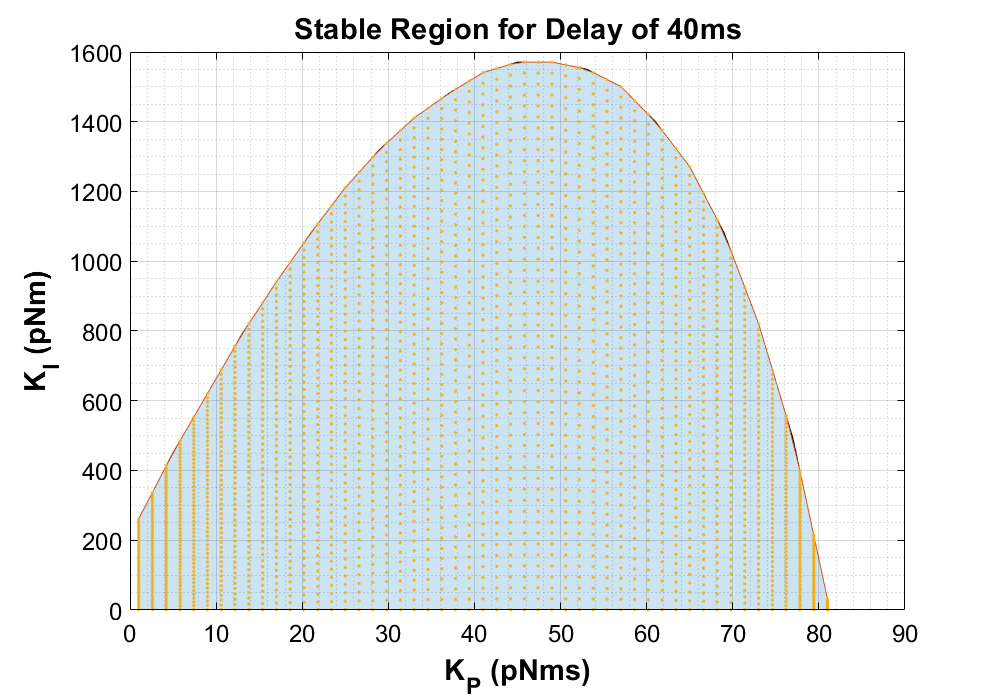

%Smooth Stability Data - Get 20ms Slice for sweeping over stable domain

slicePath = strcat(commonPath,'\Stability Sweep Data\');
latestSlice = latestTimeParse(slicePath,'02DelaySlice');
load(latestSlice)
clear slicePath latestSlice
xdata = stableSliceMax(:,1);
ydata = stableSliceMax(:,2);

%Create Figure for visualization
figure('Renderer', 'painters', 'Position', [10 10 1000 700])
a = area(xdata,ydata);
hold on
a.FaceAlpha = 0.2;
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('K_P (pNms)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I (pNm)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title('Stable Region for Delay of 20ms','FontName','Helvetica','FontSize',22,'FontWeight','bold')
grid on
grid minor
xlim([0 90])
ylim([0 1600])

%Build Stable sampling points for Ki, Kp
Kpsize = 51;
Kisize = 51;
stableSweepKp = linspace(min(xdata),max(xdata),Kpsize);
maxKiInterp = interp1(xdata(1:end-1),ydata(1:end-1),stableSweepKp);
plot(stableSweepKp,maxKiInterp)

stableSweepKi = zeros(length(stableSweepKp),Kisize);
orderedPairs = zeros(Kpsize*Kisize,2);
opIndex = 1;

%Build Ki regions
for i = 1:length(stableSweepKp)
    stableSweepKi(i,:) = linspace(1,maxKiInterp(i),Kisize);
    orderedPairs(opIndex:opIndex - 1 + Kisize,1) = stableSweepKp(i)*ones(Kisize,1);
    orderedPairs(opIndex:opIndex - 1 + Kisize,2) = stableSweepKi(i,:)';
    opIndex = opIndex + Kisize;
end

%Plot sampling points for visualization
plot(orderedPairs(:,1),orderedPairs(:,2),'.')

Kp = [10 35];
Ki = [0 150; 0 150];

# Main Sweep (All parameters minus td = 0.02)

In this section we sweep through Kp, Ki, switching threshold, and input frequency to evaluate the performance of the hybrid system.  We hold the delay time at 20ms to simulate the behavior of *D. melanogaster.*

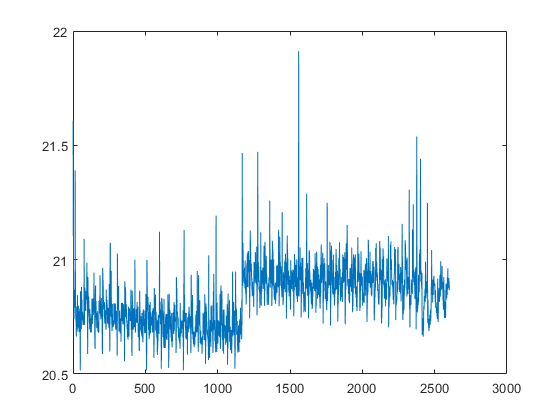

%Set up simulink model
set_param(simName,'StopTime',num2str(pureSinTime(end)),'FixedStep',num2str(pureSinTime(2) - pureSinTime(1))...
    ,'FastRestart','on')
save_system(simName)

%Create delay transfer function
td = 0.021;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);  

%Gains
Kp = stableSweepKp;
Ki = stableSweepKi;

%Setup switching threshold region and frequencies
switchThresh = 0:.005:0.5;
decimationFactor = 5;
pureSinDecimate = pureSin(5:decimationFactor:end, :);
sinfreqsDecimate = sinfreqs(5:decimationFactor:end); 
 
%Check simulation space size
innerSize = length(Kp)*length(Ki)*length(switchThresh);

%Set torque limits to inf
tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);

%FFT Parameters
Fs = 1/(pureSinTime(2)-pureSinTime(1));
N = 10000;   

%Here we preallocate all the arrays and structures to reserve memory space
%We use a struct within a struct type architecture for the hybrid and full
%data structures
emptyarray = -1000*ones(1,length(pureSinTime));
hybridStruct = repmat(struct('switchThresh',-1,'hybridOut',emptyarray,'hFit',emptyarray,'hGain',-1,'hPhase',-1,...
    'hError',-1,'hFitSAE',-1,'hSAE',-1,'hIE',-1),1,length(switchThresh));
fullStruct = struct('Kp',-1,'Ki',-1,'inputFreq',-1,'smoothOut',emptyarray,'sGain',-1,'sPhase',-1,'sError',-1,'sSAE',-1,'sIE',-1,...
    'hybridInfo',hybridStruct);
sweepData = repmat(fullStruct,size(Ki,2),size(pureSinDecimate,1));
emptySinglePoint = repmat(fullStruct,1,length(sinfreqsDecimate));

%Here we set up a plot to track simulation progress.  Y axis is the
%simulation time and x is the simulation iteration
ets = zeros(1,length(Kp)*size(Ki,2));
iter = 1;
iters = 1:1:length(Kp)*size(Ki,2);
remaining = length(Kp)*size(Ki,2); 
figure
p = plot(iters,ets);
p.XDataSource = 'iters';
p.YDataSource = 'ets';
et=0;

%Because the simulation data is so extensive, we split it into several
%files.  This ensures that only a portion of the data is stored in RAM at a
%given time.  We end up with a number of files equal to the size of the Kp
%vector.  This is a rolling buffer from memory to disk.
for i = 1:length(Kp)
    for j = 1:size(Ki,2)
        tic
        sweepData(j,:) = simTrackSmoothPrefill(Kp(i),Ki(i,j),d_tf,G_plant,pureSinDecimate,pureSinTime,sinfreqsDecimate,...
            emptySinglePoint,Fs,N,tLimSet,simName,switchThresh,td);
        
        %update tracking plot
        et = toc;
        ets(iter) = et;
        remaining = remaining-1;
        refreshdata
        drawnow
        iter = iter + 1;
    end
    
    %Save this data segment to disk
    basepath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp');
    savePath = genFileName(basepath,strcat('megaSweep_',num2str(i)));
    save(savePath,'sweepData','Kp','Ki','switchThresh','sinfreqsDecimate','pureSinTime','-v7.3')
    
    sweepData = repmat(fullStruct,length(Ki),size(pureSinDecimate,1));
    
end

# Single Point Sweeps

Here we run 3 sweeps at chosen gain sets to demonstrate representative behaviors.

## Kp = 10, Ki = 0 (*D. melanogaster*)

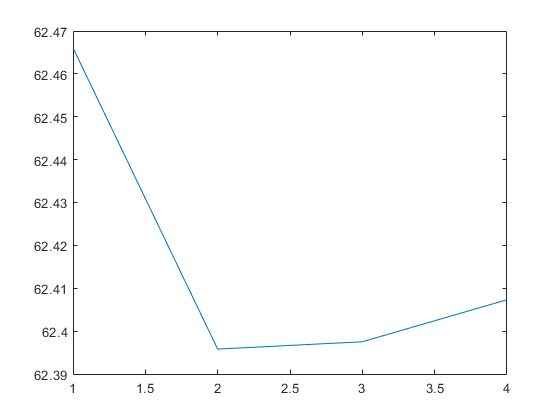

%Setup Simulink Model
set_param(simName,'StopTime',num2str(pureSinTime(end)),'FixedStep',num2str(pureSinTime(2) - pureSinTime(1))...
    ,'FastRestart','on')
save_system(simName)

%Create Delay transfer function
td = 0.021;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);  

%Setup gain arrays for kp = 10, ki=0
Kp = [10 10]; 
Ki = [0 0; 0 0];

%Small switching threshold sweep.  Setup frequencies
switchThresh = 0:.25:15;
switchThresh = switchThresh.*(pi/180);
decimationFactor = 1;
pureSinDecimate = pureSin(5:decimationFactor:end, :);
sinfreqsDecimate = sinfreqs(5:decimationFactor:end); 

%Check simulation space size
innerSize = length(Kp)*length(Ki)*length(switchThresh);

%Set torque limits to inf
tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);

%FFT Parameters
Fs = 1/(pureSinTime(2)-pureSinTime(1));
N = 10000;   

%Here we preallocate all the arrays and structures to reserve memory space
%We use a struct within a struct type architecture for the hybrid and full
%data structures
emptyarray = -1000*ones(1,length(pureSinTime));
hybridStruct = repmat(struct('switchThresh',-1,'hybridOut',emptyarray,'hFit',emptyarray,'hGain',-1,'hPhase',-1,...
    'hError',-1,'hFitSAE',-1,'hSAE',-1,'hIE',-1),1,length(switchThresh));
fullStruct = struct('Kp',-1,'Ki',-1,'inputFreq',-1,'smoothOut',emptyarray,'sGain',-1,'sPhase',-1,'sError',-1,'sSAE',-1,'sIE',-1,...
    'hybridInfo',hybridStruct);
sweepData = repmat(fullStruct,size(Ki,1),size(pureSinDecimate,1));
emptySinglePoint = repmat(fullStruct,1,length(sinfreqsDecimate));

%Here we set up a plot to track simulation progress.  Y axis is the
%simulation time and x is the simulation iteration
ets = zeros(1,length(Kp)*size(Ki,1));
iter = 1;
iters = 1:1:length(Kp)*size(Ki,1);
remaining = length(Kp)*size(Ki,1); 
figure
p = plot(iters,ets);
p.XDataSource = 'iters';
p.YDataSource = 'ets';
et=0;

%We use the same rolling buffer style here even though we are only doing a
%small sweep.  This is to allow for the usage of the common function for
%simulation.
for i = 1:length(Kp)
    for j = 1:size(Ki,1)
        tic
        sweepData(j,:) = simTrackSmoothPrefill(Kp(i),Ki(j),d_tf,G_plant,pureSinDecimate,pureSinTime,sinfreqsDecimate,...
            emptySinglePoint,Fs,N,tLimSet,simName,switchThresh,td);
        
        et = toc;
        ets(iter) = et;
        remaining = remaining-1;
        refreshdata
        drawnow
        iter = iter + 1;
    end
    
    basepath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp');
    savePath = genFileName(basepath,strcat('megaSweep_10_',num2str(i)));
    save(savePath,'sweepData','Kp','Ki','switchThresh','sinfreqsDecimate','pureSinTime','-v7.3')
    
    sweepData = repmat(fullStruct,length(Ki),size(pureSinDecimate,1));
    
end

## Kp = 18, Ki = 500

%Setup Simulink Model
set_param(simName,'StopTime',num2str(pureSinTime(end)),'FixedStep',num2str(pureSinTime(2) - pureSinTime(1))...
    ,'FastRestart','on')
save_system(simName)

%Create Delay transfer function
td = 0.021;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);  

%Setup gain arrays for kp = 10, ki=0
Kp = [18 18]; 
Ki = [500 500; 500 500];

%Small switching threshold sweep.  Setup frequencies
switchThresh = 0:.25:15;
switchThresh = switchThresh.*(pi/180);
decimationFactor = 1;
pureSinDecimate = pureSin(5:decimationFactor:end, :);
sinfreqsDecimate = sinfreqs(5:decimationFactor:end); 

%Check simulation space size
innerSize = length(Kp)*length(Ki)*length(switchThresh);

%Set torque limits to inf
tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);

%FFT Parameters
Fs = 1/(pureSinTime(2)-pureSinTime(1));
N = 10000;   

%Here we preallocate all the arrays and structures to reserve memory space
%We use a struct within a struct type architecture for the hybrid and full
%data structures
emptyarray = -1000*ones(1,length(pureSinTime));
hybridStruct = repmat(struct('switchThresh',-1,'hybridOut',emptyarray,'hFit',emptyarray,'hGain',-1,'hPhase',-1,...
    'hError',-1,'hFitSAE',-1,'hSAE',-1,'hIE',-1),1,length(switchThresh));
fullStruct = struct('Kp',-1,'Ki',-1,'inputFreq',-1,'smoothOut',emptyarray,'sGain',-1,'sPhase',-1,'sError',-1,'sSAE',-1,'sIE',-1,...
    'hybridInfo',hybridStruct);
sweepData = repmat(fullStruct,size(Ki,1),size(pureSinDecimate,1));
emptySinglePoint = repmat(fullStruct,1,length(sinfreqsDecimate));

%Here we set up a plot to track simulation progress.  Y axis is the
%simulation time and x is the simulation iteration
ets = zeros(1,length(Kp)*size(Ki,1));
iter = 1;
iters = 1:1:length(Kp)*size(Ki,1);
remaining = length(Kp)*size(Ki,1); 
figure
p = plot(iters,ets);
p.XDataSource = 'iters';
p.YDataSource = 'ets';
et=0;

%We use the same rolling buffer style here even though we are only doing a
%small sweep.  This is to allow for the usage of the common function for
%simulation.
for i = 1:length(Kp)
    for j = 1:size(Ki,1)
        tic
        sweepData(j,:) = simTrackSmoothPrefill(Kp(i),Ki(j),d_tf,G_plant,pureSinDecimate,pureSinTime,sinfreqsDecimate,...
            emptySinglePoint,Fs,N,tLimSet,simName,switchThresh,td);
        
        et = toc;
        ets(iter) = et;
        remaining = remaining-1;
        refreshdata
        drawnow
        iter = iter + 1;
    end
    
    basepath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp');
    savePath = genFileName(basepath,strcat('megaSweep_18_',num2str(i)));
    save(savePath,'sweepData','Kp','Ki','switchThresh','sinfreqsDecimate','pureSinTime','-v7.3')
    
    sweepData = repmat(fullStruct,length(Ki),size(pureSinDecimate,1));
    
end


## Kp = 60, Ki = 700

%Setup Simulink Model
set_param(simName,'StopTime',num2str(pureSinTime(end)),'FixedStep',num2str(pureSinTime(2) - pureSinTime(1))...
    ,'FastRestart','on')
save_system(simName)

%Create Delay transfer function
td = 0.021;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);  

%Setup gain arrays for kp = 60, ki=700
Kp = [60 60]; 
Ki = [700 700; 700 700];

%Small switching threshold sweep.  Setup frequencies
switchThresh = 0:.25:15;
switchThresh = switchThresh.*(pi/180);
decimationFactor = 1;
pureSinDecimate = pureSin(5:decimationFactor:end, :);
sinfreqsDecimate = sinfreqs(5:decimationFactor:end); 

%Check simulation space size
innerSize = length(Kp)*length(Ki)*length(switchThresh);

%Set torque limits to inf
tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);

%FFT Parameters
Fs = 1/(pureSinTime(2)-pureSinTime(1));
N = 10000;   

%Here we preallocate all the arrays and structures to reserve memory space
%We use a struct within a struct type architecture for the hybrid and full
%data structures
emptyarray = -1000*ones(1,length(pureSinTime));
hybridStruct = repmat(struct('switchThresh',-1,'hybridOut',emptyarray,'hFit',emptyarray,'hGain',-1,'hPhase',-1,...
    'hError',-1,'hFitSAE',-1,'hSAE',-1,'hIE',-1),1,length(switchThresh));
fullStruct = struct('Kp',-1,'Ki',-1,'inputFreq',-1,'smoothOut',emptyarray,'sGain',-1,'sPhase',-1,'sError',-1,'sSAE',-1,'sIE',-1,...
    'hybridInfo',hybridStruct);
sweepData = repmat(fullStruct,size(Ki,1),size(pureSinDecimate,1));
emptySinglePoint = repmat(fullStruct,1,length(sinfreqsDecimate));

%Here we set up a plot to track simulation progress.  Y axis is the
%simulation time and x is the simulation iteration
ets = zeros(1,length(Kp)*size(Ki,1));
iter = 1;
iters = 1:1:length(Kp)*size(Ki,1);
remaining = length(Kp)*size(Ki,1); 
figure
p = plot(iters,ets);
p.XDataSource = 'iters';
p.YDataSource = 'ets';
et=0;

%We use the same rolling buffer style here even though we are only doing a
%small sweep.  This is to allow for the usage of the common function for
%simulation.
for i = 1:length(Kp)
    for j = 1:size(Ki,1)
        tic
        sweepData(j,:) = simTrackSmoothPrefill(Kp(i),Ki(j),d_tf,G_plant,pureSinDecimate,pureSinTime,sinfreqsDecimate,...
            emptySinglePoint,Fs,N,tLimSet,simName,switchThresh,td);
        
        et = toc;
        ets(iter) = et;
        remaining = remaining-1;
        refreshdata
        drawnow
        iter = iter + 1;
    end
    
    basepath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp');
    savePath = genFileName(basepath,strcat('megaSweep_60_',num2str(i)));
    save(savePath,'sweepData','Kp','Ki','switchThresh','sinfreqsDecimate','pureSinTime','-v7.3')
    
    sweepData = repmat(fullStruct,length(Ki),size(pureSinDecimate,1));
    
end

# Discussion Sweep

We do a final sweep here at some interesting points for discussion.

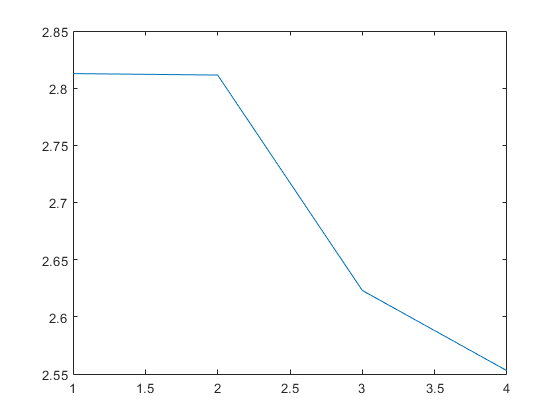

set_param(simName,'StopTime',num2str(pureSinTime(end)),'FixedStep',num2str(pureSinTime(2) - pureSinTime(1))...
    ,'FastRestart','on')
save_system(simName)

td = 0.021;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);  

Kp = [10 18];
Ki = [0 500; 0 500];

switchThresh = 0:.01:0.1;
decimationFactor = 5;
pureSinDecimate = pureSin(5:decimationFactor:end, :);
sinfreqsDecimate = sinfreqs(5:decimationFactor:end); 
 
innerSize = length(Kp)*length(Ki)*length(switchThresh);
tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);

%FFT Params
Fs = 1/(pureSinTime(2)-pureSinTime(1));
N = 10000;   


emptyarray = -1000*ones(1,length(pureSinTime));
hybridStruct = repmat(struct('switchThresh',-1,'hybridOut',emptyarray,'hFit',emptyarray,'hGain',-1,'hPhase',-1,...
    'hError',-1,'hFitSAE',-1,'hSAE',-1,'hIE',-1),1,length(switchThresh));
fullStruct = struct('Kp',-1,'Ki',-1,'inputFreq',-1,'smoothOut',emptyarray,'sGain',-1,'sPhase',-1,'sError',-1,'sSAE',-1,'sIE',-1,...
    'hybridInfo',hybridStruct);
sweepData = repmat(fullStruct,size(Ki,2),size(pureSinDecimate,1));
emptySinglePoint = repmat(fullStruct,1,length(sinfreqsDecimate));

ets = zeros(1,length(Kp)*size(Ki,2));
iter = 1;
iters = 1:1:length(Kp)*size(Ki,2);
remaining = length(Kp)*size(Ki,2); 
figure
p = plot(iters,ets);
p.XDataSource = 'iters';
p.YDataSource = 'ets';
et=0;

for i = 1:length(Kp)
    for j = 1:size(Ki,2)
        tic
        sweepData(j,:) = simTrackSmoothPrefill(Kp(i),Ki(i,j),d_tf,G_plant,pureSinDecimate,pureSinTime,sinfreqsDecimate,...
            emptySinglePoint,Fs,N,tLimSet,simName,switchThresh,td);
        
        et = toc;
        ets(iter) = et;
        remaining = remaining-1;
        refreshdata
        drawnow
        iter = iter + 1;
    end
    
    basepath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp');
    savePath = genFileName(basepath,strcat('megaSweep_disc_',num2str(i)));
    save(savePath,'sweepData','Kp','Ki','switchThresh','sinfreqsDecimate','pureSinTime','-v7.3')
    
    sweepData = repmat(fullStruct,length(Ki),size(pureSinDecimate,1));
    
end